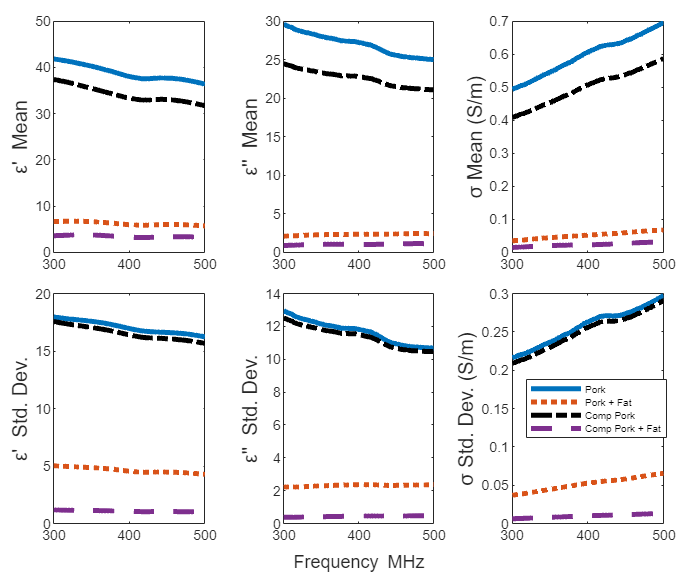

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork+Fat\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork+Fat\";
%paste in your csv or xlsx files here:

% DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\New Pork\Pork\";
% DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\New Pork\Pork+Fat\";
% DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\Compressed Pork\Pork\";
% DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\Compressed Pork\Pork+Fat\";

FileNames = [
    "PF T1.csv";
    "PF T2.csv";
    "PF T3.csv";
    "PF T4.csv";
    "PF T5.csv";
    "PF T6.csv";
    "PF T7.csv";
    "PF T8.csv";
    "PF T9.csv";
    "PF T10.csv";
    "PF T11.csv";
    "PF T12.csv";
    "PF T13.csv";
    "PF T14.csv";
    "PF T15.csv";
    "PF T16.csv";
    "PF T17.csv";
    "PF T18.csv";
    "PF T19.csv";
    "PF T20.csv";
    "PF T21.csv";
    "PF T22.csv";
    "PF T23.csv";
    "PF T24.csv";
    "PF T25.csv";
    "PF T26.csv";
    "PF T27.csv";
    "PF T28.csv";
    "PF T29.csv";
    "PF T30.csv";
    "PF T31.csv";
    "PF T32.csv";
    "PF T33.csv";
    "PF T34.csv";
    "PF T35.csv";
    "PF T36.csv";
    "PF T37.csv";
    "PF T38.csv";
    "PF T39.csv";
    "PF T40.csv";
    "PF T41.csv";
    "PF T42.csv";
    "PF T43.csv";
    "PF T44.csv";
    "PF T45.csv";
    "PF T46.csv";
    "PF T47.csv";
    "PF T48.csv";
    "PF T49.csv";
    "PF T50.csv";
    "PF T51.csv";
    "PF T52.csv";
    "PF T53.csv";
    "PF T54.csv";
    "PF T55.csv";
    "PF T56.csv";
    "PF T57.csv";
    "PF T58.csv";
    "PF T59.csv";
    "PF T60.csv";
    "PF T61.csv";
    "PF T62.csv";
    "PF T63.csv";
    "PF T64.csv";
    "PF T65.csv";
    "PF T66.csv";
    "PF T67.csv";
    "PF T68.csv";
    "PF T69.csv";
    "PF T70.csv";
    ];

FileCount = 1:70;

%Old version of epsilon text on plots
%ylabel(' $\varepsilon^{\prime \prime}$ Mean','interpreter','latex', "FontSize", 15);

%New version of setting up epsilon text... Pain in the ass.
epsilon_p_m = char(949) + "'  Mean";
epsilon_p_std = char(949) + "'  Std. Dev.";
epsilon_pp_m = char(949) + "''  Mean";
epsilon_pp_std = char(949) + "''  Std. Dev.";
sigma_m = char(963) + " Mean (S/m)";
sigma_std = char(963) + " Std. Dev. (S/m)";

%FOR Thesis plots it was [1, 1, 600, 500]
%FOR IEEE plots it was [1, 1, 500, 300]
figure('Position', [1, 1, 600, 500])
t = tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
xlabel(t, sprintf('Frequency {MHz}'),'interpreter','tex', 'FontSize', 11);

%Epsilon Prime Mean
nexttile
[x, y, z, w, ~, ~, ~, ~, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(epsilon_p_m, "FontSize", 12);


%Epsilon Double Prime Mean
nexttile
[x, y, z, w, ~, ~, ~, ~, freq] = plotEpsDoublePrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(epsilon_pp_m, "FontSize", 12);

%Conductivity Mean
nexttile
[x, y, z, w, ~, ~, ~, ~, freq] = plotConductivityStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(sigma_m, "FontSize", 12);


%Epsilon Prime Standard Deviation
nexttile
[~, ~, ~, ~, x, y, z, w, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(epsilon_p_std, "FontSize", 12);
% ylim([0 30]);


%Epsilon Double Prime Standard Deviation
nexttile
[~, ~, ~, ~, x, y, z, w, freq] = plotEpsDoublePrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(epsilon_pp_std, "FontSize", 12);


%Conductivity Standard Deviation
nexttile
[~, ~, ~, ~, x, y, z, w, freq] = plotConductivityStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);
plot(freq, x, 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','--', 'LineWidth', 3);
hold off;
ylabel(sigma_std, "FontSize", 12);
legend('Pork', 'Pork + Fat', 'Comp Pork', 'Comp Pork + Fat', 'Location', 'west', "FontSize", 6);


% figure('Position', [1, 1, 600, 250])
% t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
% xlabel(t, sprintf('Frequency {MHz}\n \\bf (a) '),'interpreter','tex', 'FontSize', 11);
% 
% % Tile 1
% nexttile
% plot(frequencies, e_mean);
% hold on;
% plot(frequencies, e_std);
% ylabel(' $\varepsilon^{\prime}$ ','interpreter','latex', "FontSize", 18);
% hold on
% %legend("Mean", "Standard Deviation");
% 
% nexttile
% plot(frequencies, ee_std);
% hold on;
% plot(frequencies, ee_mean);
% ylabel(' $\varepsilon^{\prime \prime}$ ','interpreter','latex', "FontSize", 18);
% legend("Mean", "Standard Deviation");


% debug
% [sigma, sigma2, sigma3, sigma4, w] = plotConductivityStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount);

sigma_m = "σ Mean (S/m)"

sigma_std = "σ Std. Dev. (S/m)"

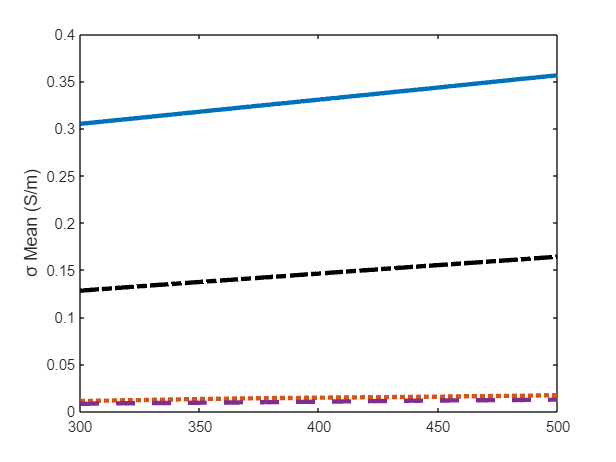

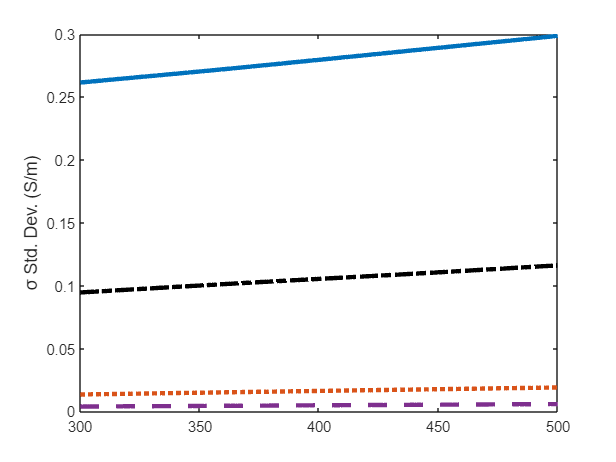

function [e_mean, e_mean2, e_mean3, e_mean4, e_std, e_std2, e_std3, e_std4, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount)


    % Preallocate a matrix to store the data
    % 30 measurements and 201 frequency points
e_all = zeros(30, 201); 
e_all2 = zeros(30, 201); 
e_all3 = zeros(30, 201); 
e_all4 = zeros(30, 201); 
%ee_all = zeros(30, 201);

for loopFiles = FileCount
    % Read the matrix for this file
    VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14); %14 skips the 14 headers
    VNA_Zdata2 = readmatrix(strcat(DirectoryName2,FileNames(loopFiles,:)), 'Range', 14);
    VNA_Zdata3 = readmatrix(strcat(DirectoryName3,FileNames(loopFiles,:)), 'Range', 14); 
    VNA_Zdata4 = readmatrix(strcat(DirectoryName4,FileNames(loopFiles,:)), 'Range', 14); 

    % Store the entire frequency range's measurement
    % for the current measurement file. Adjust the columns as necessary.
    e_all(loopFiles, :) = VNA_Zdata(:, 2).'; % Transpose to match the row orientation
    e_all2(loopFiles, :) = VNA_Zdata2(:, 2).';
    e_all3(loopFiles, :) = VNA_Zdata3(:, 2).'; 
    e_all4(loopFiles, :) = VNA_Zdata4(:, 2).'; 
    
    %ee_all(loopFiles, :) = VNA_Zdata(:, 3).'; % Transpose to match the row orientation
end

e_mean = mean(e_all, 1); % 1 specifies to operate along the rows \\MEAN
e_mean2 = mean(e_all2, 1);
e_mean3 = mean(e_all3, 1);
e_mean4 = mean(e_all4, 1);
e_std = std(e_all, 0, 1); % 0 for default normalization, 1 to operate along the rows \\STD
e_std2 = std(e_all2, 0, 1);
e_std3 = std(e_all3, 0, 1);
e_std4 = std(e_all4, 0, 1);

freq = linspace(300, 500, 201); % Generates 201 linearly spaced points from 300 to 500

end

function [ee_mean, ee_mean2, ee_mean3, ee_mean4, ee_std, ee_std2, ee_std3, ee_std4, freq] = plotEpsDoublePrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount)

    % Preallocate a matrix to store the data
    % 30 measurements and 201 frequency points
ee_all = zeros(30, 201); 
ee_all2 = zeros(30, 201); 
ee_all3 = zeros(30, 201); 
ee_all4 = zeros(30, 201); 

for loopFiles = FileCount
    % Read the matrix for this file
    VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14); %14 skips the 14 headers
    VNA_Zdata2 = readmatrix(strcat(DirectoryName2,FileNames(loopFiles,:)), 'Range', 14);
    VNA_Zdata3 = readmatrix(strcat(DirectoryName3,FileNames(loopFiles,:)), 'Range', 14); 
    VNA_Zdata4 = readmatrix(strcat(DirectoryName4,FileNames(loopFiles,:)), 'Range', 14); 

    % Store the entire frequency range's measurement
    % for the current measurement file. Adjust the columns as necessary.
    ee_all(loopFiles, :) = VNA_Zdata(:, 3).'; % Transpose to match the row orientation
    ee_all2(loopFiles, :) = VNA_Zdata2(:, 3).';
    ee_all3(loopFiles, :) = VNA_Zdata3(:, 3).';
    ee_all4(loopFiles, :) = VNA_Zdata4(:, 3).';
    
end

ee_mean = mean(ee_all, 1); % 1 specifies to operate along the rows \\MEAN
ee_mean2 = mean(ee_all2, 1);
ee_mean3 = mean(ee_all3, 1);
ee_mean4 = mean(ee_all4, 1);
ee_std = std(ee_all, 0, 1); % 0 for default normalization, 1 to operate along the rows \\STD
ee_std2 = std(ee_all2, 0, 1);
ee_std3 = std(ee_all3, 0, 1);
ee_std4 = std(ee_all4, 0, 1);

freq = linspace(300, 500, 201); % Generates 201 linearly spaced points from 300 to 500

end


function [c_mean, c_mean2, c_mean3, c_mean4, c_std, c_std2, c_std3, c_std4, freq] = plotConductivityStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount)
% function [sigma, sigma2, sigma3, sigma4, w] = plotConductivityStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount)
    % Preallocate a matrix to store the data
    % 30 measurements and 201 frequency points
ee_all = zeros(30, 201); 
ee_all2 = zeros(30, 201); 
ee_all3 = zeros(30, 201); 
ee_all4 = zeros(30, 201);
sigma = zeros(30, 201); 
sigma2 = zeros(30, 201); 
sigma3 = zeros(30, 201); 
sigma4 = zeros(30, 201);


for loopFiles = FileCount
    % Read the matrix for this file
    VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14); %14 skips the 14 headers
    VNA_Zdata2 = readmatrix(strcat(DirectoryName2,FileNames(loopFiles,:)), 'Range', 14);
    VNA_Zdata3 = readmatrix(strcat(DirectoryName3,FileNames(loopFiles,:)), 'Range', 14); 
    VNA_Zdata4 = readmatrix(strcat(DirectoryName4,FileNames(loopFiles,:)), 'Range', 14); 

    % Store the entire frequency range's measurement
    % for the current measurement file. Adjust the columns as necessary.
    ee_all(loopFiles, :) = VNA_Zdata(:, 3).'; % Transpose to match the row orientation
    ee_all2(loopFiles, :) = VNA_Zdata2(:, 3).';
    ee_all3(loopFiles, :) = VNA_Zdata3(:, 3).';
    ee_all4(loopFiles, :) = VNA_Zdata4(:, 3).';

    w = 2*pi.*VNA_Zdata(:,1).';
    eps_o = 8.854*10^-12;

    sigma(loopFiles, :) = w.*eps_o.*ee_all(loopFiles, :); % Transpose to match the row orientation
    sigma2(loopFiles, :) = w.*eps_o.*ee_all2(loopFiles, :);
    sigma3(loopFiles, :) = w.*eps_o.*ee_all3(loopFiles, :);
    sigma4(loopFiles, :) = w.*eps_o.*ee_all4(loopFiles, :);
end

c_mean = mean(sigma, 1); % 1 specifies to operate along the rows \\MEAN
c_mean2 = mean(sigma2, 1);
c_mean3 = mean(sigma3, 1);
c_mean4 = mean(sigma4, 1);
c_std = std(sigma, 0, 1); % 0 for default normalization, 1 to operate along the rows \\STD
c_std2 = std(sigma2, 0, 1);
c_std3 = std(sigma3, 0, 1);
c_std4 = std(sigma4, 0, 1);

freq = linspace(300, 500, 201); % Generates 201 linearly spaced points from 300 to 500

end










%Code for saving the resulting data to excel files for use in simulations
% Write the 30x201 matrix data to an Excel file
% writematrix(all_measurements, 'all_measurements.xlsx');
% % Convert mean_measurements to a table
% mean_table = table(frequencies.', mean_measurements.', 'VariableNames', {'Frequency_MHz', 'Mean_Value'});
% % Write the mean values to an Excel file
% writetable(mean_table, 'mean_values.xlsx');
% % Convert std_measurements to a table
% std_table = table(frequencies.', std_measurements.', 'VariableNames', {'Frequency_MHz', 'Std_Deviation'});
% % Write the standard deviation values to an Excel file
% writetable(std_table, 'std_deviation.xlsx');


% function [e_mean, e_std, ee_mean, ee_std, freq] = plotEpsMSTD(DirectoryName,FileNames, FileCount)
% 
%     % Preallocate a matrix to store the data
%     % 30 measurements and 201 frequency points
% e_all = zeros(30, 201); 
% ee_all = zeros(30, 201);
% 
% for loopFiles = FileCount
%     % Read the matrix for this file
%     VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14); %14 skips the 14 headers
% 
%     % Store the entire frequency range's measurement
%     % for the current measurement file. Adjust the columns as necessary.
%     e_all(loopFiles, :) = VNA_Zdata(:, 2).'; % Transpose to match the row orientation
%     ee_all(loopFiles, :) = VNA_Zdata(:, 3).'; % Transpose to match the row orientation
% end
% 
% e_mean = mean(e_all, 1); % 1 specifies to operate along the rows \\MEAN
% e_std = std(e_all, 0, 1); % 0 for default normalization, 1 to operate along the rows \\STD
% ee_mean = mean(ee_all, 1);
% ee_std = std(ee_all, 0, 1);
% freq = linspace(300, 500, 201); % Generates 201 linearly spaced points from 300 to 500
% 
% end
